# Evaluate a Network

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

rng(123)
pathToImages = "../data/Animals/";
imds = imageDatastore(pathToImages, "IncludeSubfolders", true, "LabelSource", "foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Deep_Learning_with_MATLAB\data\Animals\Alpaca\01ad3ff1d94eb557.jpg';
                              ' ...\Deep_Learning_with_MATLAB\data\Animals\Alpaca\0346463867a297f4.jpg';
                              ' ...\Deep_Learning_with_MATLAB\data\Animals\Alpaca\038fae9e70c4c3f1.jpg'
                               ... and 439 more
                              }
                     Folders: {
                              ' ...\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\Animals'
                              }
                      Labels: [Alpaca; Alpaca; Alpaca ... and 439 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
            

[trainImgs, testImgs] = splitEachLabel(imds, 0.95);
trainds = augmentedImageDatastore([224 224], trainImgs);
testds = augmentedImageDatastore([224 224], testImgs);

## Load and train Deep Network

load ../data/animals_lgraph.mat
options = trainingOptions("adam", "InitialLearnRate", 0.0001, VerboseFrequency=1, MaxEpochs=10)

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 1
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment:

animalsnet = trainNetwork(trainds, lgraph, options)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:15 |       35.16% |       2.4736 |      1.0000e-04 |
|       1 |           2 |       00:00:29 |       53.91% |       1.1362 |      1.0000e-04 |
|       1 |           3 |       00:00:43 |       67.97% |       0.7071 |      1.0000e-04 |
|       2 |           4 |       00:00:58 |       82.03% |       0.3792 |      1.0000e-04 |
|       2 |           5 |       00:01:12 |       92.97% |       0.2303 |      1.0000e-04 |
|       2 |           6 |       00:01:27 |       92.19% |       0.1845 |      1.0000e-04 |
|       3 |           7 |  

animalsnet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


## Task 1

The first section of the script contains code to split a datastore into two separate datastores. If you would like to see these variables in the Workspace, you can enter the command `whos` in the script and click the green **Run** button in the Toolstrip.

You can predict the labels for new images with the `classify` function.

`predictedLabels` `=` `classify``(``net``,``imds``)`

testPreds = classify(animalsnet, testds);

## Task 2

You can calculate the testing accuracy by comparing the labels in the test image datastore with the predicted labels from the network.

`nnz``(``trueLabels` `==` `predictedLabels``)` `/` `n`

Here `n` is the number of test images. The `nnz` function counts the number of non-zero elements, or the number of elements where the true label equals the predicted label.

acc = nnz(testPreds == testImgs.Labels) / length(testPreds)

acc = 1

## Task 3

The confusion matrix shows which labels were misclassified.

`confusionchart``(``known``,``predicted``)`

The x-axis of this matrix is the predicted label, and the y-axis is the known label. For example, in the third row and fifth column, Lucy was misclassified as Susan.

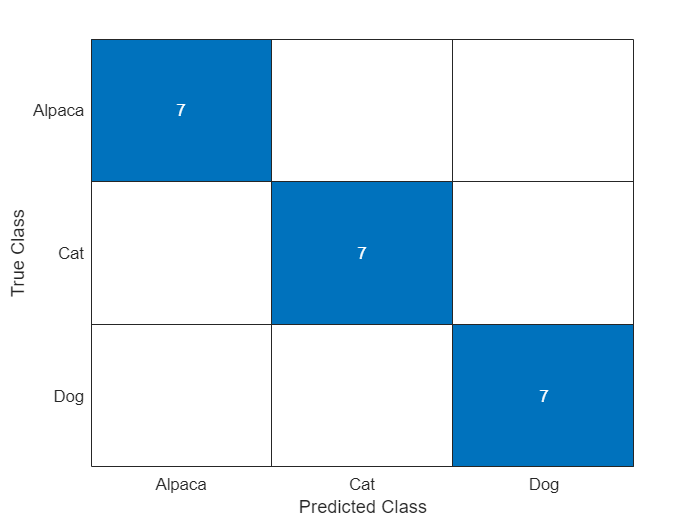

confusionchart(testImgs.Labels, testPreds)